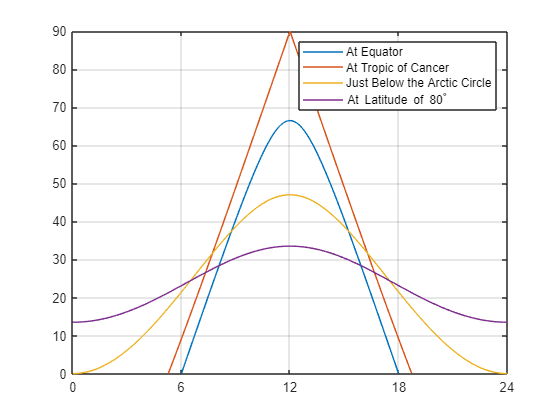

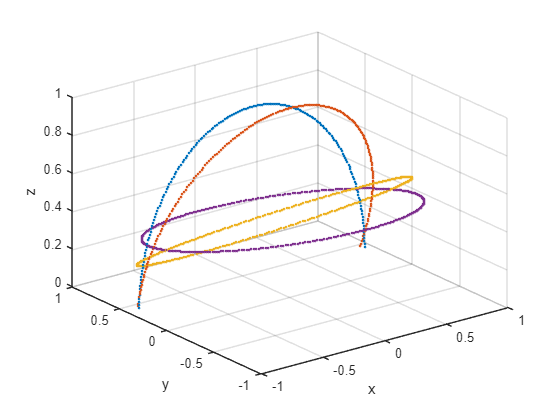

    %Que5
%Q4
clear vars
close all
%sun's coordinate for Que 5
ps = [cosd(23.5); 0; sind(23.5)]; % PS
%all latitudes to be considered
phi =[0 23.5 66.5 80]; 
%iterating through phi == latitude.
for k = 1:4
    phi_k = phi(k);                                 % selecting a phi to work on
    theta = -180:180;                               % theta = longitude, west - east kind  == phiDegSet in sir's assisgnment.
    azimuthals = zeros(1,361);                      %alphas to be stored == azimuthal angle.
    betas = zeros(1,361);                           %Betas to be stored == elevation angle.
    SENU = zeros(3, 361);                           %all coordinates in ENU to be stored.
    %iterating through the thetas / longitudes 
    for i = theta
                                                    %R matrix from webpage mentioned in assignment :
                                                    %webpage link : https://gssc.esa.int/navipedia/index.php/Transformations_between_ECEF_and_ENU_coordinates
        
        R = [-sind(i)             cosd(i)               0;
             -1*cosd(i)*sind(phi_k)  -1*sind(i)*sind(phi_k)   cosd(phi_k);
             cosd(i)*cosd(phi_k)     sind(i)*cosd(phi_k)      sind(phi_k)];
                                                   
        Cor_in_ENU = R * ps; % 1 x 3                
        azimuthals(i + 181) = atand(Cor_in_ENU(2)/ Cor_in_ENU(1)); % 1 x 361
        betas(i + 181) = atand(Cor_in_ENU(3)/(sqrt(Cor_in_ENU(1).^2 + Cor_in_ENU(2).^2)));
        SENU(1:3, i + 181) = Cor_in_ENU; % 3 x 361
        %elevation = atan2(Cor_in_ENU(3), sqrt(Cor_in_ENU(1).^2 + Cor_in_ENU(2).^2));
    end
    Nset = length(theta);
    t0 = linspace(0,24, Nset);

    iF = betas > 0;
    figure(1);
    plot3(SENU(1, iF), SENU(2, iF), SENU(3, iF), '.');
    xlabel('x'); ylabel('y'); zlabel('z');
    ylim([-1 1]);
    grid;
    grid on;
    hold on;
    %legend([{'At Equator'},{'At Tropic of Cancer'},{'Just Below the Arctic Circle'},{'At Latitude of 80^{\circ}'}]);
    figure(2);
    plot(t0, betas);
    set(gca, 'xtick', 0:6:24);
    legend('At Equator','At Tropic of Cancer','Just Below the Arctic Circle','At Latitude of 80^{\circ}');
    axis([0 24 0 90]);
    grid on;
    hold on;
end

%%%% functions %%%%%%